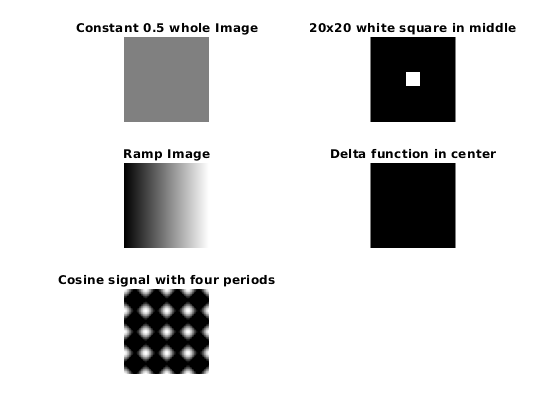

% Task 1
clear all;
I = zeros(128);
figure;
% Constant value 0.5 for whole image.
I1=I+0.5;
subplot (3,2,1);
imshow(I1);
title("Constant 0.5 whole Image")

I2=I;
% 20x20 white square in the middle
I2(54:74,54:74)=1;
subplot (3,2,2);
imshow(I2);
title("20x20 white square in middle")

% Ramp from 0 to 1 in horizontal axis, constant in vertical axis.
I3=((repmat([0:1:255]',1,256)))'/256;
subplot (3,2,3); 
imshow(I3);
title("Ramp Image")

% Delta function at the center of the image.
I4=I;
I4(64,64)=1;
subplot (3,2,4);
imshow(I4);
title("Delta function in center")

% Cosine signal having four periods in both directions
x=0:1:127;
f=cos((2*pi*x)/32);
[fe1,fe2]=meshgrid(f,f);
I5=(fe1+fe2)/2;
subplot (3,2,5);
imshow(I5);
title("Cosine signal with four periods")

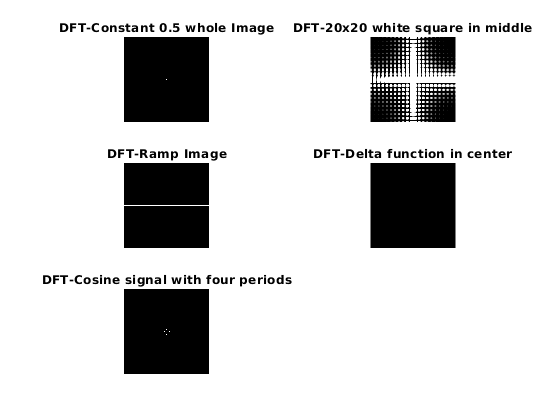

%%% Task 2
%% a
[dft1,g1]=DFT(I1);
[dft2,g2]=DFT(I2);
[dft3,g3]=DFT(I3);
[dft4,g4]=DFT(I4);
[dft5,g5]=DFT(I5);
figure
subplot (3,2,1);
imshow(dft1);
title("DFT-Constant 0.5 whole Image")
subplot (3,2,2); 
imshow(dft2);
title("DFT-20x20 white square in middle")
subplot (3,2,3);
imshow(dft3);
title("DFT-Ramp Image")
subplot (3,2,4);
imshow(dft4);
title("DFT-Delta function in center")
subplot (3,2,5);
imshow(dft5);
title("DFT-Cosine signal with four periods")

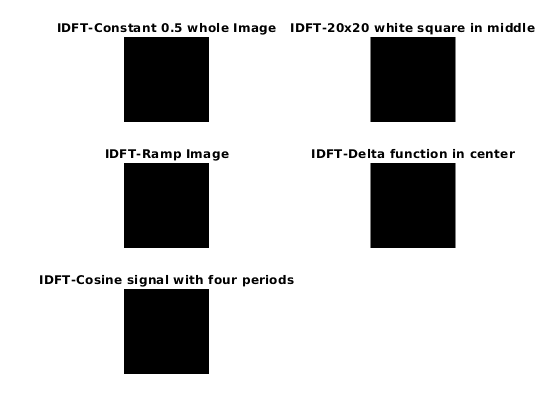


figure;
subplot (3,2,1);
imshow(uint8(g1));
title("IDFT-Constant 0.5 whole Image")
subplot (3,2,2); 
imshow(uint8(g2));
title("IDFT-20x20 white square in middle")
subplot (3,2,3);
imshow(uint8(g3));
title("IDFT-Ramp Image")
subplot (3,2,4);
imshow(uint8(g4));
title("IDFT-Delta function in center")
subplot (3,2,5);
imshow(uint8(g5));
title("IDFT-Cosine signal with four periods")



%% b
%  The output of the transformation represents the image in the Fourier domain 
%  the image in the Fourier domain is decomposed into its sinusoidal (sine/cosine)
%  components,
%  it makes it easy to examine or process certain frequencies of the image.
%% c
% The result shows that the image contains components of all frequencies, 
% but that their magnitude gets smaller for higher frequencies. 
% Hence, low frequencies contain more image information than the higher ones. 


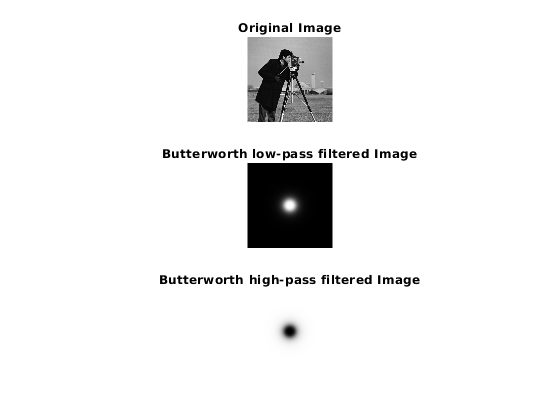

% Task 3
clear all
I = imread('cameraman.tif');
D0 = 20;
n  = 2;
figure
f1 = BWLPfilter(I, D0, n);
subplot (3,1,1);
imshow(I);
title("Original Image")
subplot (3,1,2);
imshow(f1)
title("Butterworth low-pass filtered Image")
f2=1-f1;
subplot (3,1,3);
imshow(f2);
title("Butterworth high-pass filtered Image")

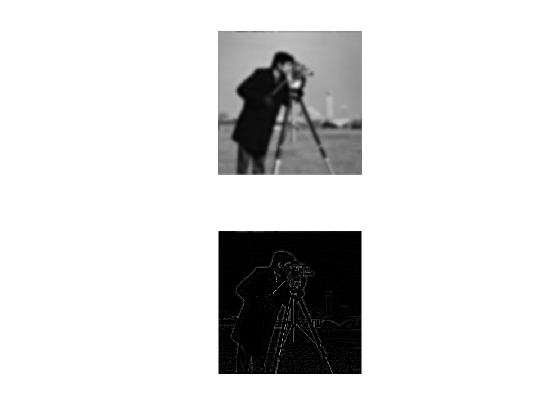


F=fft2(I);
Fc=fftshift(F);
G1 = f1.*Fc;
G2 = f2.*Fc;
% Do inverse shifting and inverse transform
gi1 = ifft2(ifftshift(G1));
gi2 = ifft2(ifftshift(G2));
% Take the real part
g1 = real(gi1); 
g2 = real(gi2);

figure;
subplot(2,1,1)
imshow(uint8(g1)); 
subplot(2,1,2)
imshow(uint8(g2));